% FIR Filter design using fir1() with Hamming Window
clc;
clear all;
close all;

load('100m.mat')

ECGsignal_original = (val -1024)/100;
Fs = 360;

%Frequency of PowerLine Interference
f1 = 50;   

t = (0:length(ECGsignal_original)-1)/Fs;

%Generating Noise for f1 = 50 Hz
N= 0.1*cos (2*pi*f1*t);

%Adding Noise to ECG signal
ECG_Noise = ECGsignal_original + N;

%Specifications
wc = 0.2778*pi;
R_p = 1;
R_s = 40;
ws = 0.305*pi;
wp = 0.25*pi;
dw=ws-wp;

%Order of Filter
M_hamming=6.64*pi/dw;

Y=fir1(ceil(M_hamming),wc/pi);

%Transfer Function for FIR Filter
tf = tf(Y,1,1/Fs)

tf =
 
  0.0002397 z^121 + 0.0004291 z^120 + 0.0003183 z^119 - 3.935e-05 z^118 - 0.0004133 z^117 - 0.0005286 z^116 - 0.0002539 z^115 + 0.0002743 z^114 + 0.0006963 z^113 + 0.0006558 z^112 + 8.03e-05 z^111 - 0.0006927 z^110 - 0.001088 z^109 - 0.0006979 z^108 + 0.0003432 z^107 + 0.001345 z^106 + 0.001491 z^105 + 0.0004743 z^104 - 0.00114 z^103 - 0.002185 z^102 - 0.001707 z^101 + 0.0002225 z^100 + 0.002356 z^99 + 0.00304 z^98 + 0.001456 z^97 - 0.001567 z^96 - 0.003909 z^95 - 0.003604 z^94 - 0.0004255 z^93 + 0.003634 z^92 + 0.005548 z^91 + 0.00346 z^90 - 0.001668 z^89 - 0.00634 z^88 - 0.006847 z^87 - 0.002119 z^86 + 0.005015 z^85 + 0.009408 z^84 + 0.007209 z^83 - 0.00094 z^82 - 0.009687 z^81 - 0.01235 z^80 - 0.005854 z^79 + 0.006302 z^78 + 0.01566 z^77 + 0.01445 z^76 + 0.001693 z^75 - 0.01484 z^74 - 0.02297 z^73 - 0.01461 z^72 + 0.007296 z^71 + 0.02867 z^70 + 0.03242 z^69 + 0.01062 z^68 - 0.02732 z^67 - 0.05652 z^66 - 0.04936 z^65 + 0.007837 z^64 + 0.1038 z^63 + 0.2045 z^62 + 0.2688 z^61 + 

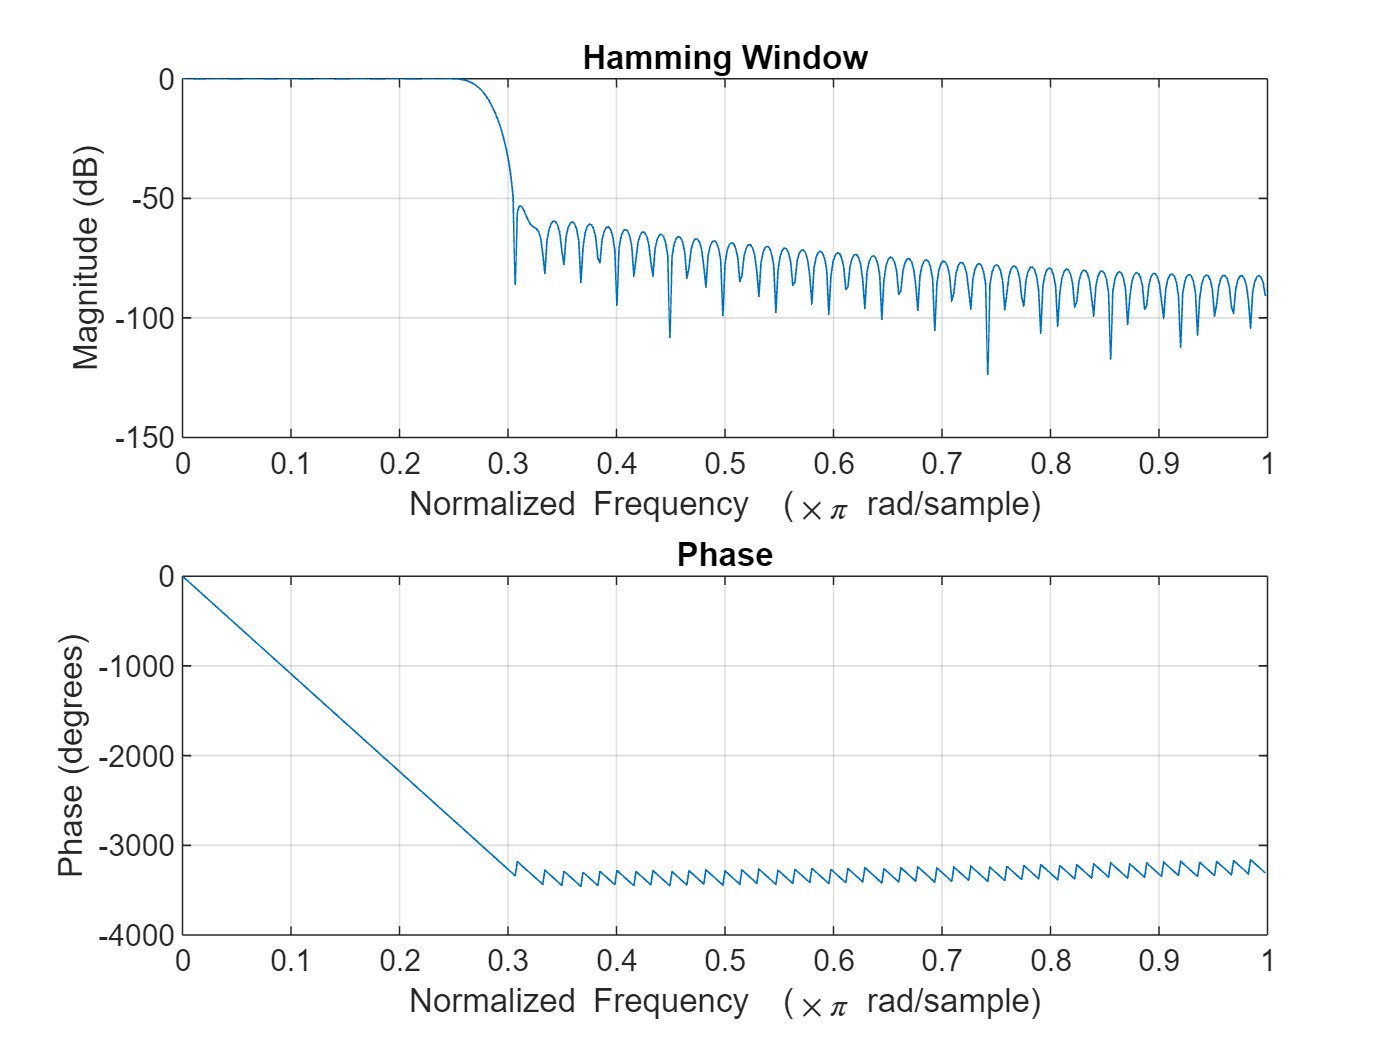

freqz(Y,1);
title("Hamming Window")

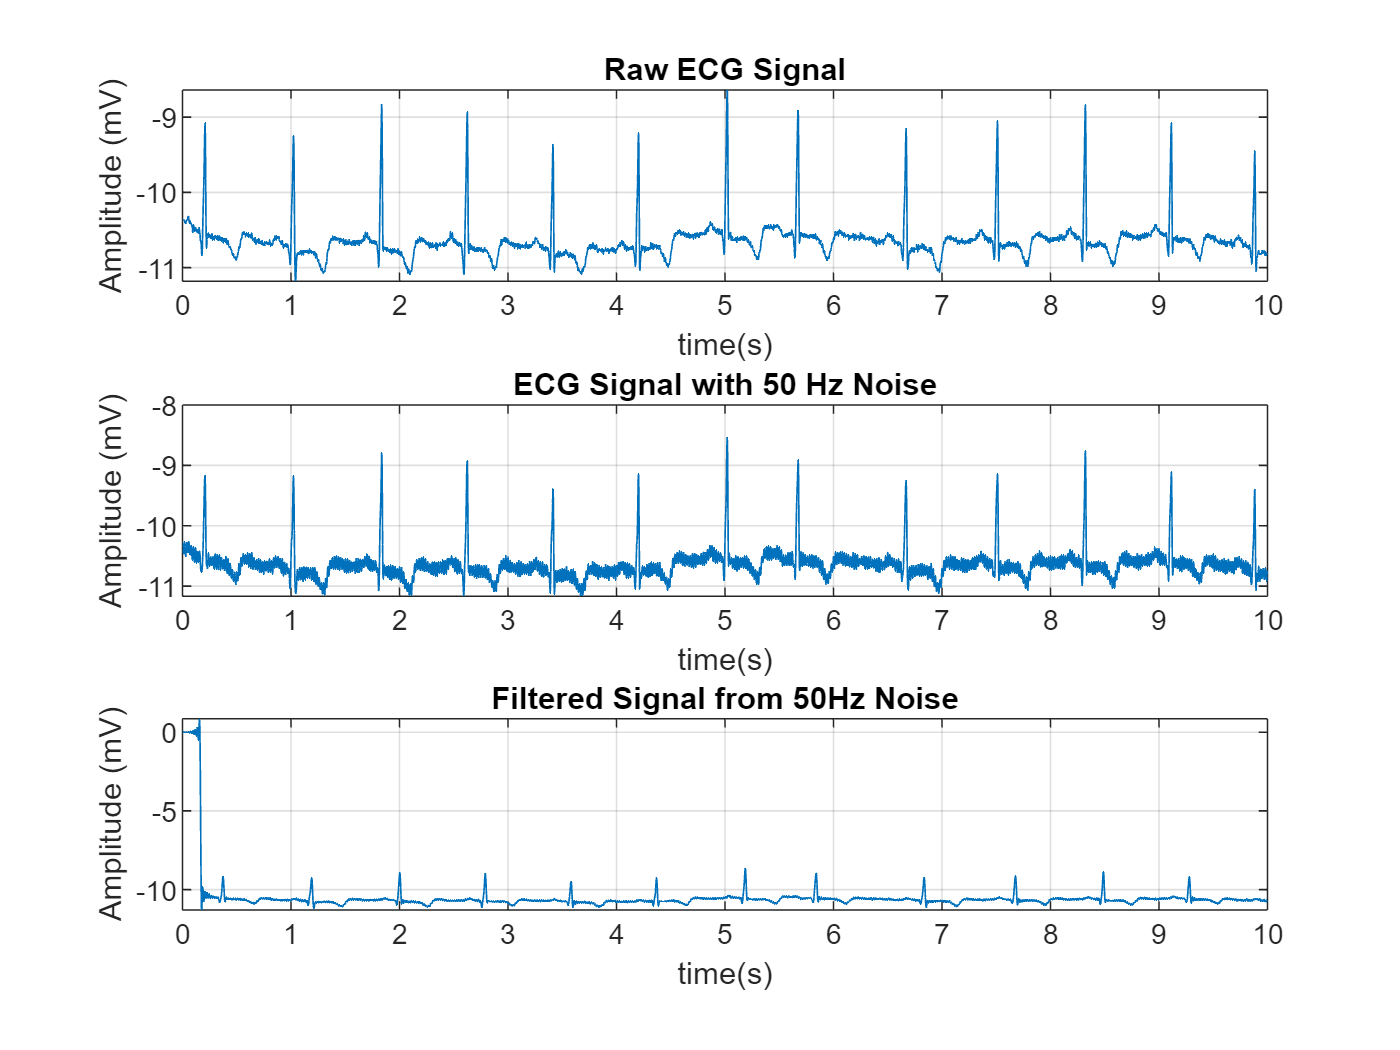

%Filtering the Noisy Signal
ECG_Filtered = filter(Y,1,ECG_Noise);

%Plotting 
subplot(3,1,1)
plot(t,ECGsignal_original)
xlabel('time(s)')
ylabel('Amplitude (mV)')
title('Raw ECG Signal')
grid on
subplot(3,1,2)
plot(t,ECG_Noise)
xlabel('time(s)')
ylabel('Amplitude (mV)')
title('ECG Signal with 50 Hz Noise')
grid on
subplot(3,1,3)
plot(t,ECG_Filtered)
xlabel('time(s)')
ylabel('Amplitude (mV)')
title('Filtered Signal from 50Hz Noise')
grid on